# Project 15: Group 1

## 1. Define directory and compile audio into audiodatastore

clear
clc
dir

.                                                                          
..                                                                         
Data Look.txt                                                              
Data Look.xlsm                                                             
P15 Challenge - Elephant Listening Project - Use Case Details dec 15.docx  
Raponi et al Sound of guns.pdf                                             
data                                                                       
getAudio.asv                                                               
getAudio.m                                                                 
getData.m                                                                  
gunshots                                                                   
main.mlx                                                                   
main_v2.mlx                                                                
maybe gunsho

% define folder name where .wav gunshot training files are.
folder = 'data';

% organise audio files into table (dataframe)
[table_data, nfiles] = getData(folder);

tic
% can set to find read audio based on hour
% 0-1 is 0, 1-2 is 1... 22-23 is 22. Cannot exceed 22.
hr = 12;
[y, Fs] = getAudio(table_data.filename(1), folder, hr)

y =    -0.0067   -0.0181   -0.0180   -0.0490   -0.0260   -0.0126   -0.0110   -0.0119   -0.0167   -0.0132   -0.0123   -0.0215   -0.0287   -0.0292   -0.0057   -0.0221   -0.0233   -0.0326   -0.0340   -0.0284   -0.0048    0.0124   -0.0193   -0.0107   -0.0202   -0.0143   -0.0166   -0.0189   -0.0206   -0.0148
   -0.0063   -0.0188    0.0107   -0.0315   -0.0267   -0.0193   -0.0078   -0.0228   -0.0170   -0.0125   -0.0132   -0.0103   -0.0055   -0.0251   -0.0040   -0.0264   -0.0201   -0.0313   -0.0146   -0.0273   -0.0075   -0.0390   -0.0220   -0.0196   -0.0236   -0.0151   -0.0168   -0.0218   -0.0166   -0.0174
   -0.0015   -0.0188   -0.0350   -0.0125   -0.0108   -0.0166   -0.0093   -0.0176   -0.0174   -0.0121   -0.0146   -0.0165   -0.0308   -0.0222   -0.0100   -0.0205   -0.0175   -0.0291   -0.0325   -0.0218   -0.0092   -0.0070   -0.0161   -0.0172   -0.0158   -0.0251   -0.0191   -0.0182   -0.0137   -0.0176
   -0.0060   -0.0155    0.0060   -0.0297   -0.0297   -0.0150   -0.0080   -0.0153   -0.0161   

Fs = 8000

toc

Elapsed time is 0.827301 seconds.


% convert test audio ELP to time table
y_test = array2timetable(y, "SampleRate", Fs)

y_test = 959235×30 timetable
        Time            y1            y2            y3           y4            y5            y6            y7           y8            y9           y10          y11          y12          y13           y14          y15           y16          y17          y18          y19           y20          y21           y22           y23          y24           y25          y26          y27          y28          y29          y30   
    ____________

% define folder where comparison 'training' gunshot audios are
folder_train = 'gunshots';

[table_train, nfiles] = getData(folder_train);

% read training gunshot audio files
tic
file_train = fullfile(folder_train, table_train.filename(1))

file_train = "gunshots\nn01a_20180203_1230.wav"

[y_train, Fs] = audioread(file_train)

y_train =    -0.0052
   -0.0066
   -0.0052
   -0.0075
   -0.0189
   -0.0200
   -0.0162
   -0.0187
   -0.0222
   -0.0168


Fs = 8000

toc

Elapsed time is 0.031094 seconds.


% convert training gunshot audio to time table
gunshotTT = array2timetable(y_train, "SampleRate", Fs)

gunshotTT = 9480×1 timetable
        Time         y_train  
    ____________    __________

    0 sec           -0.0051575
    0.000125 sec    -0.0065918
    0.00025 sec      -0.005249
    0.000375 sec    -0.0075073
    0.0005 sec        -0.01886
    0.000625 sec     -0.019958
    0.00075 sec      -0.016235
    0.000875 sec     -0.018738
    0.001 sec        -0.022186
    0.001125 sec     -0.016785
    0.00125 sec      -0.023285
    0.001375 sec     -0.023865
    0.0015 sec       -0.016693
    0.001625 sec     -0.016693
    0.00175 sec       -0.01178
    0.001875 sec     -0.016846


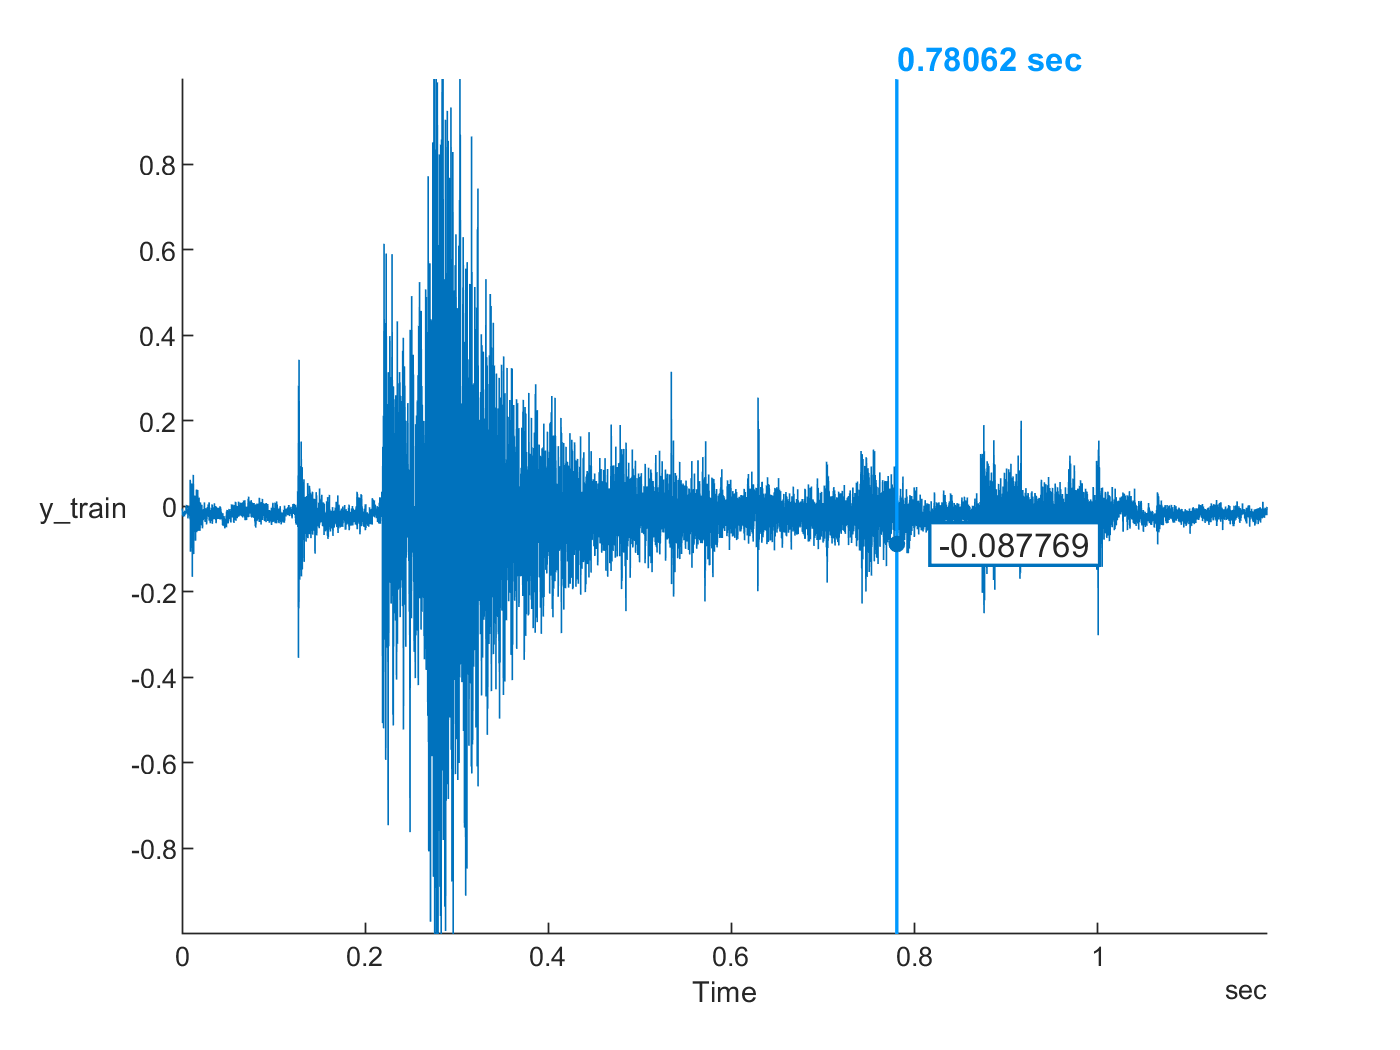


% preview gunshot training audio from ELP
stackedplot(gunshotTT)

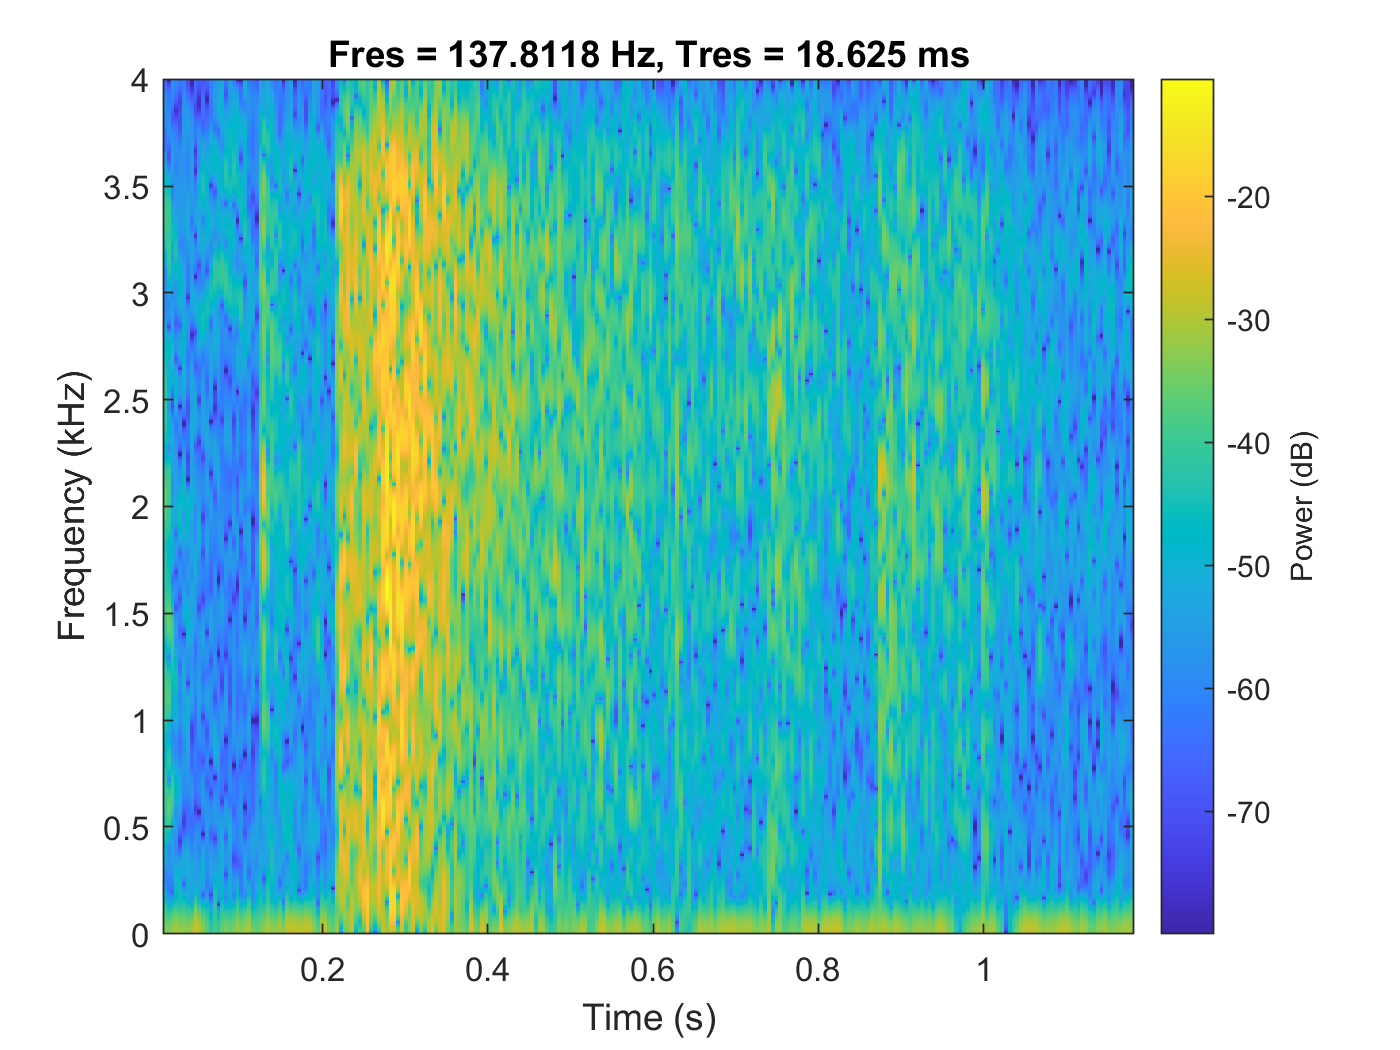

pspectrum(gunshotTT, 'spectrogram', 'MinThreshold', -80)

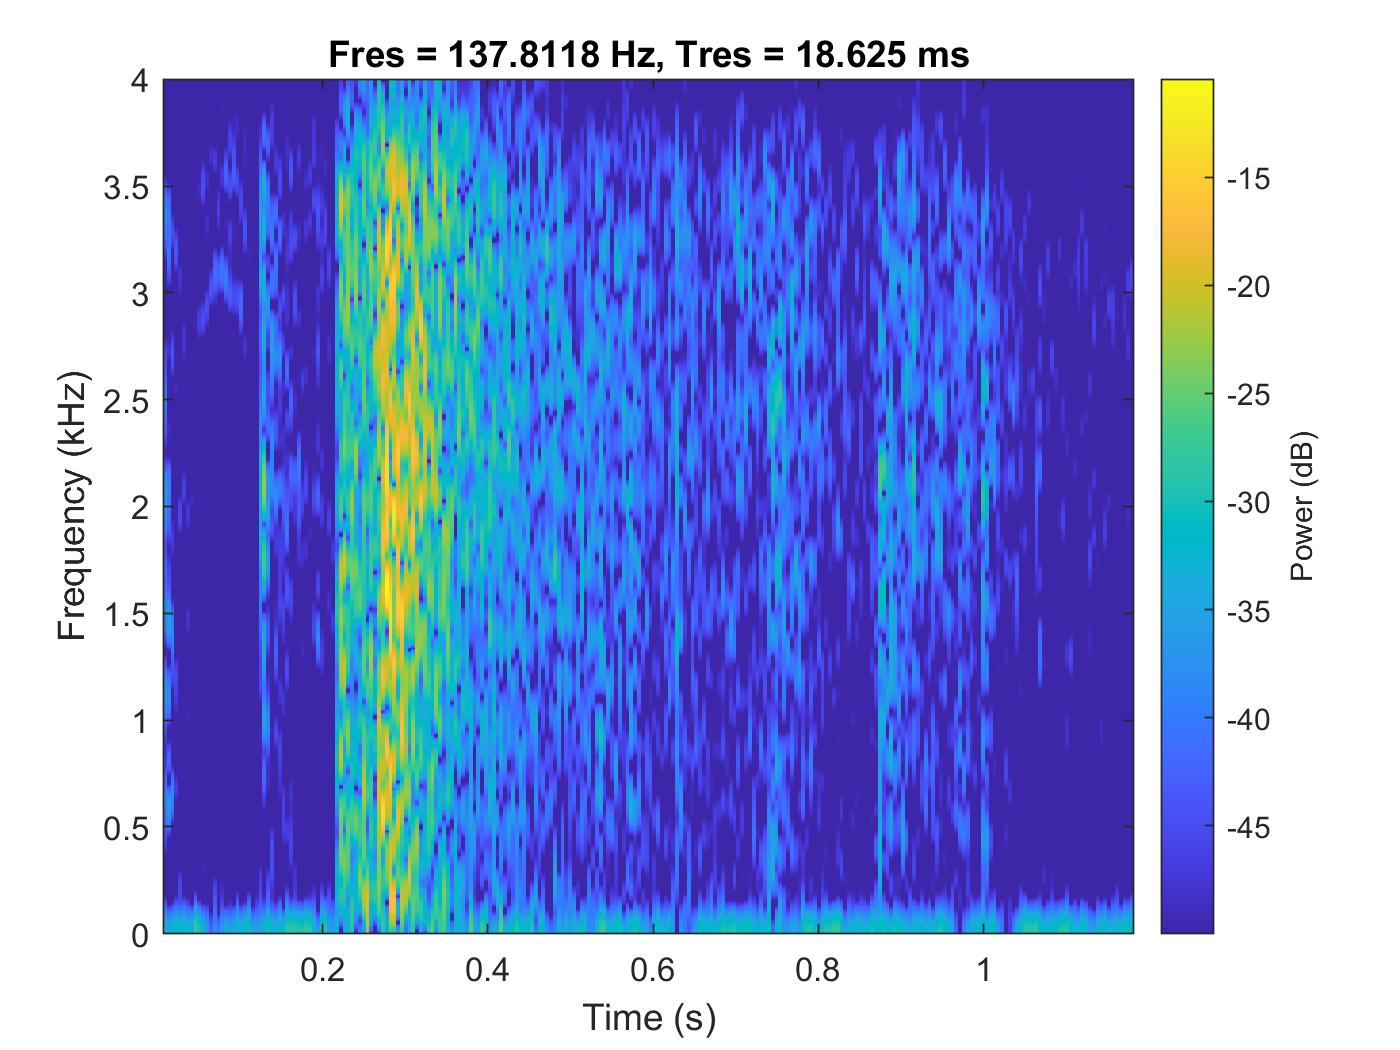

pspectrum(gunshotTT, 'spectrogram', 'MinThreshold', -50)

win = hamming(Fs/2, 'periodic')

win =     0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800


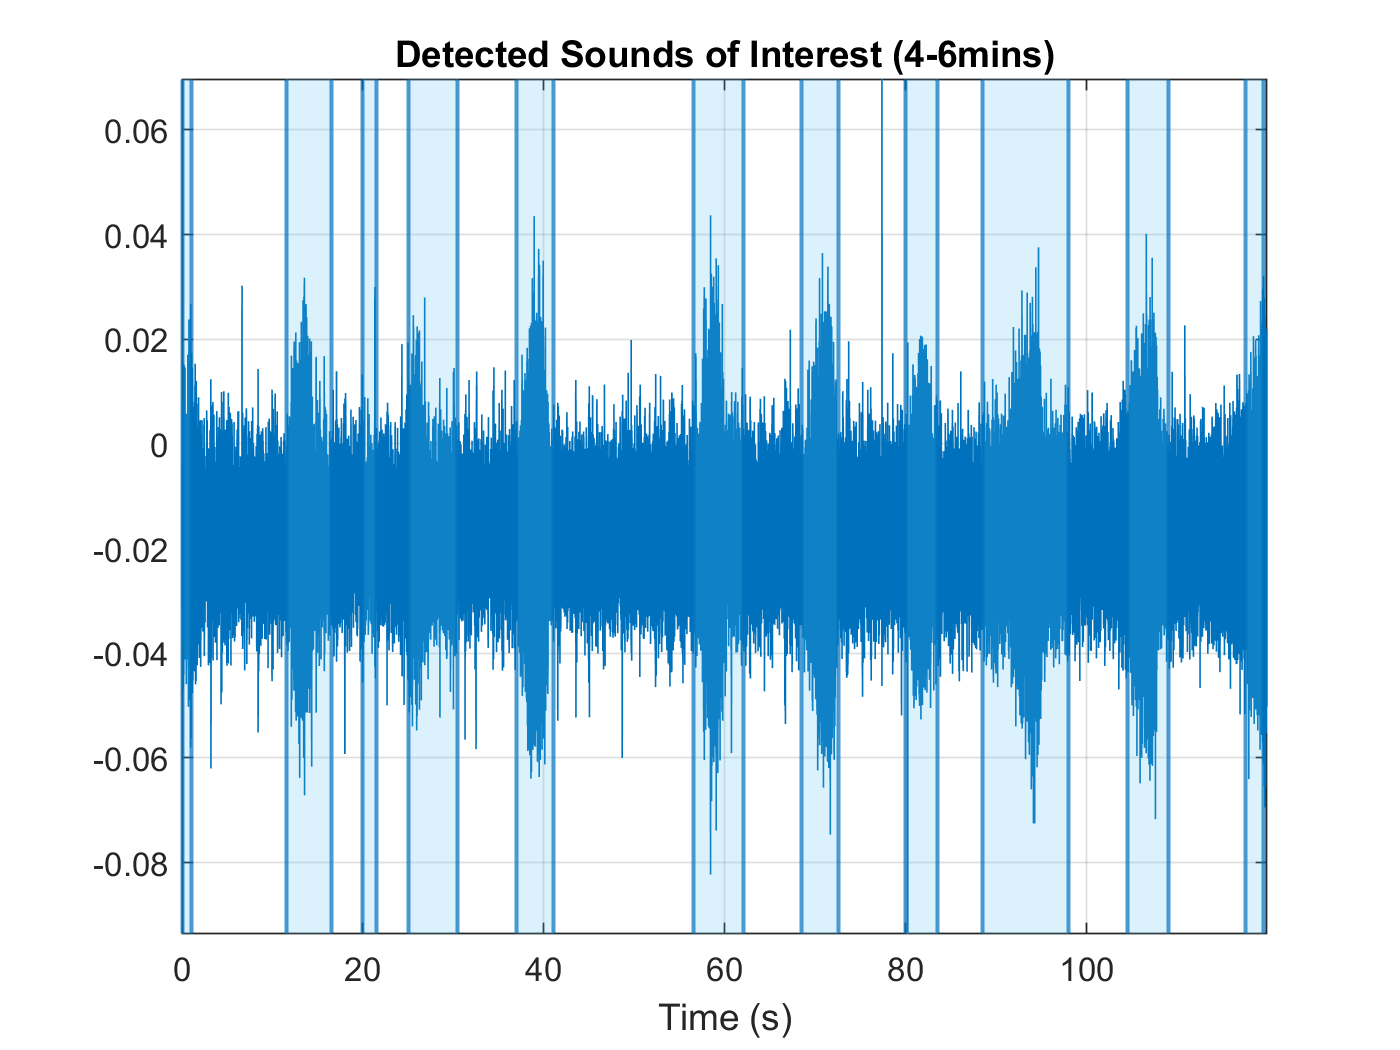

detectSpeech(y(:,2), Fs, "Window", win)
title('Detected Sounds of Interest (4-6mins)')

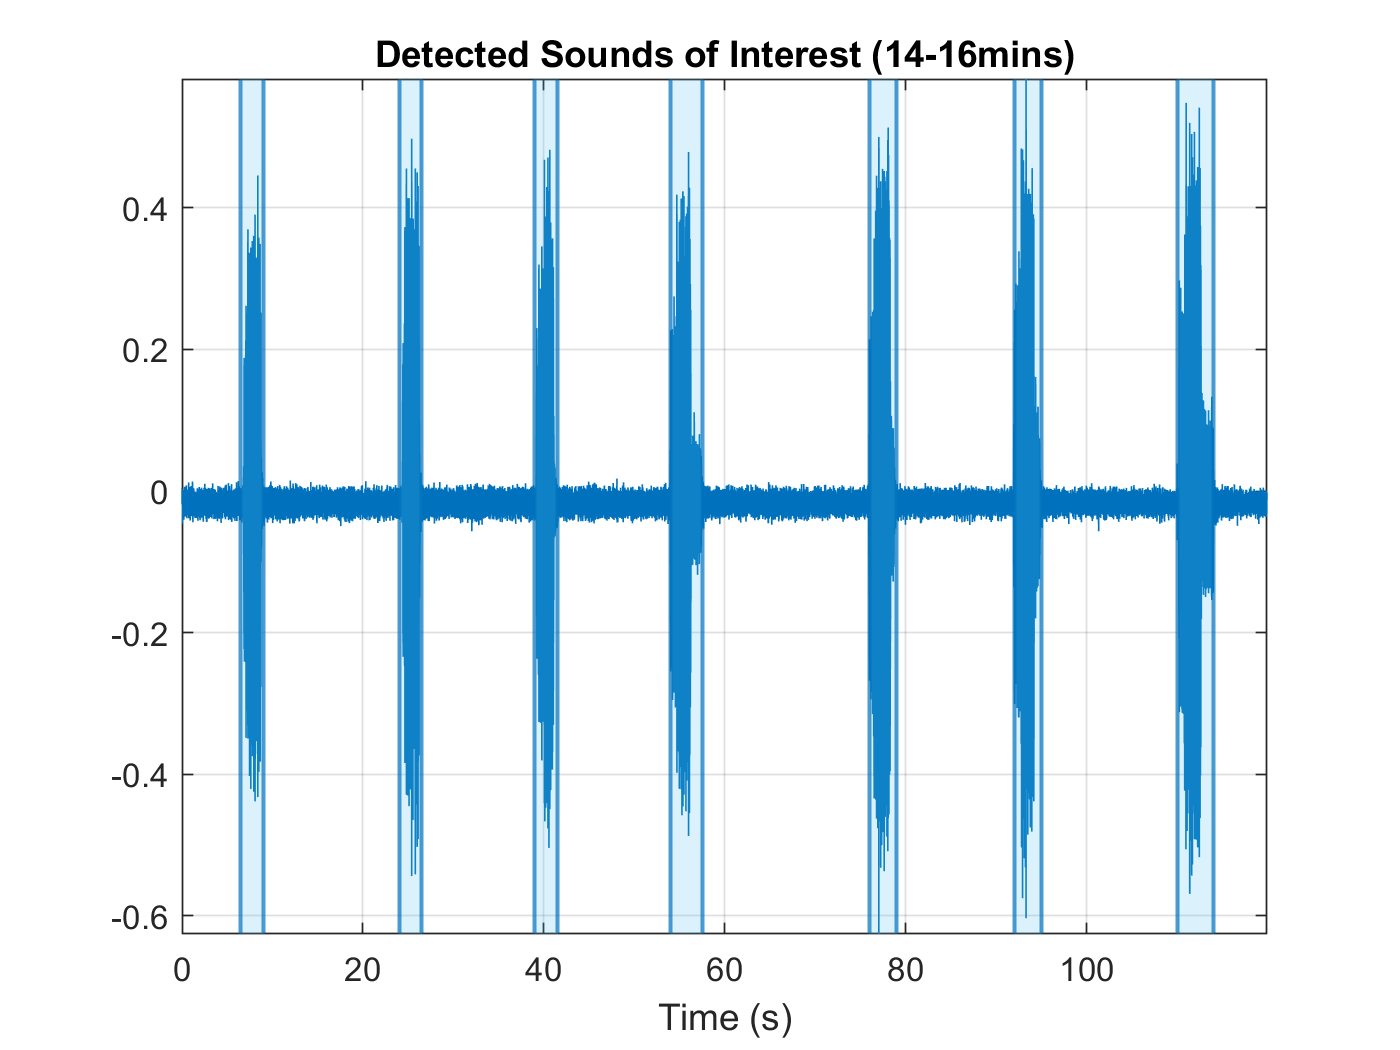

detectSpeech(y(:,7), Fs, "Window", win)
title('Detected Sounds of Interest (14-16mins)')

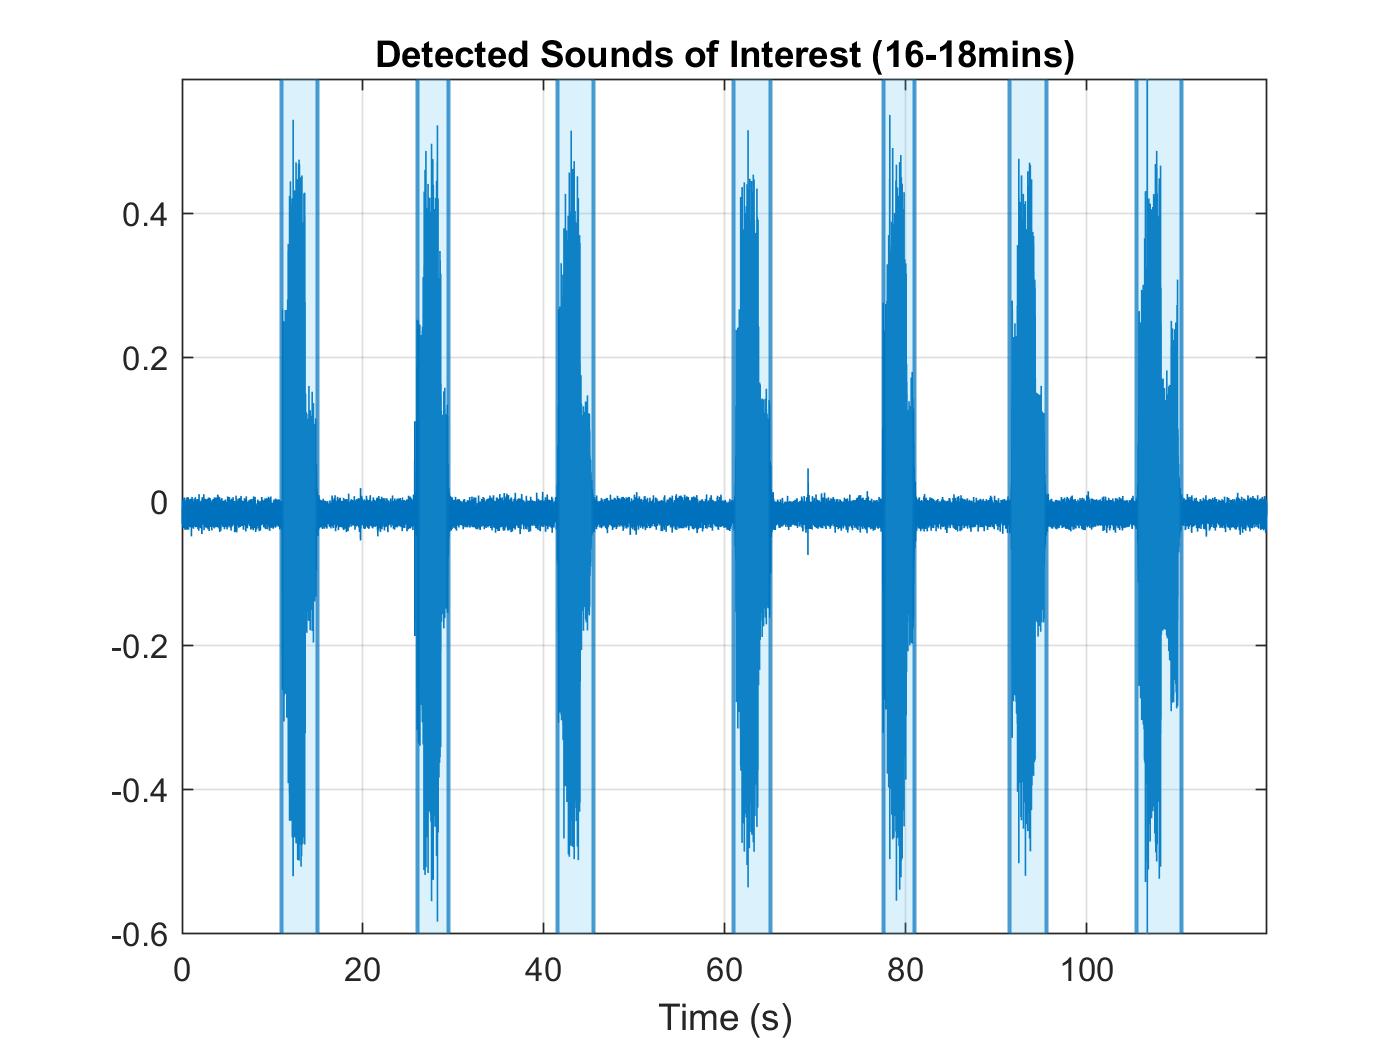

detectSpeech(y(:,8), Fs, "Window", win)
title('Detected Sounds of Interest (16-18mins)')

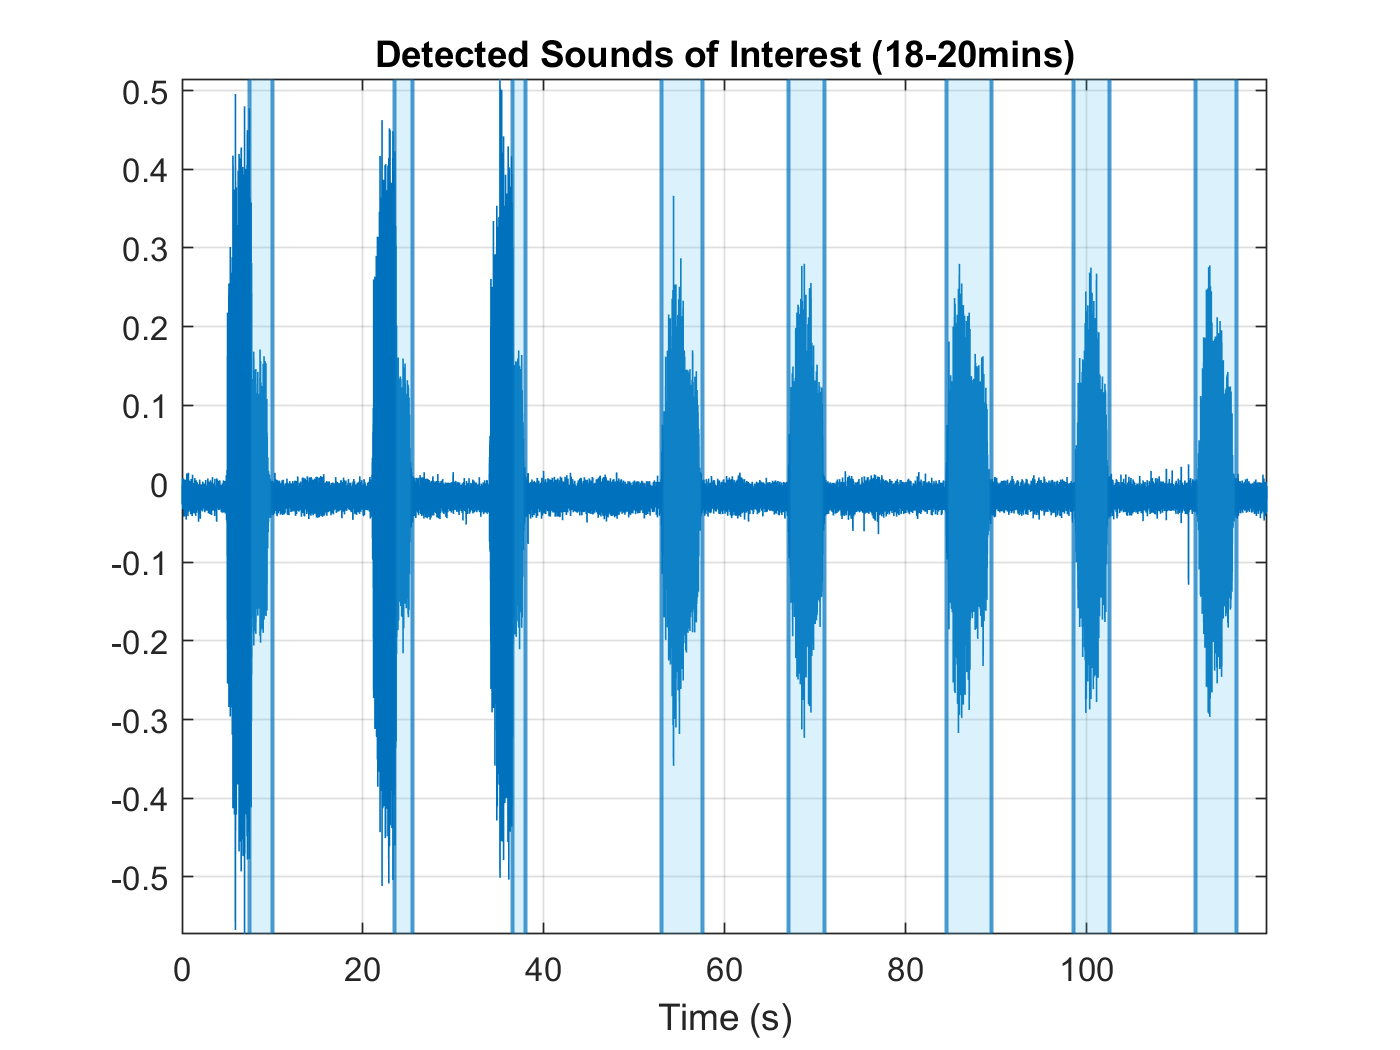

detectSpeech(y(:,9), Fs, "Window", win)
title('Detected Sounds of Interest (18-20mins)')